clear;
m = 100000;
n = 10000;
density = 2/m;
lda = 0.01;
rho = 0.1;
abs_tolerance = 1e-4;
rel_tolerance = 1e-3;
x = sprand(m, n, density);
theta = rand(n, 1);
noise = -0.5 + rand(m, 1);
y = x*theta + noise;
iters = 1000;

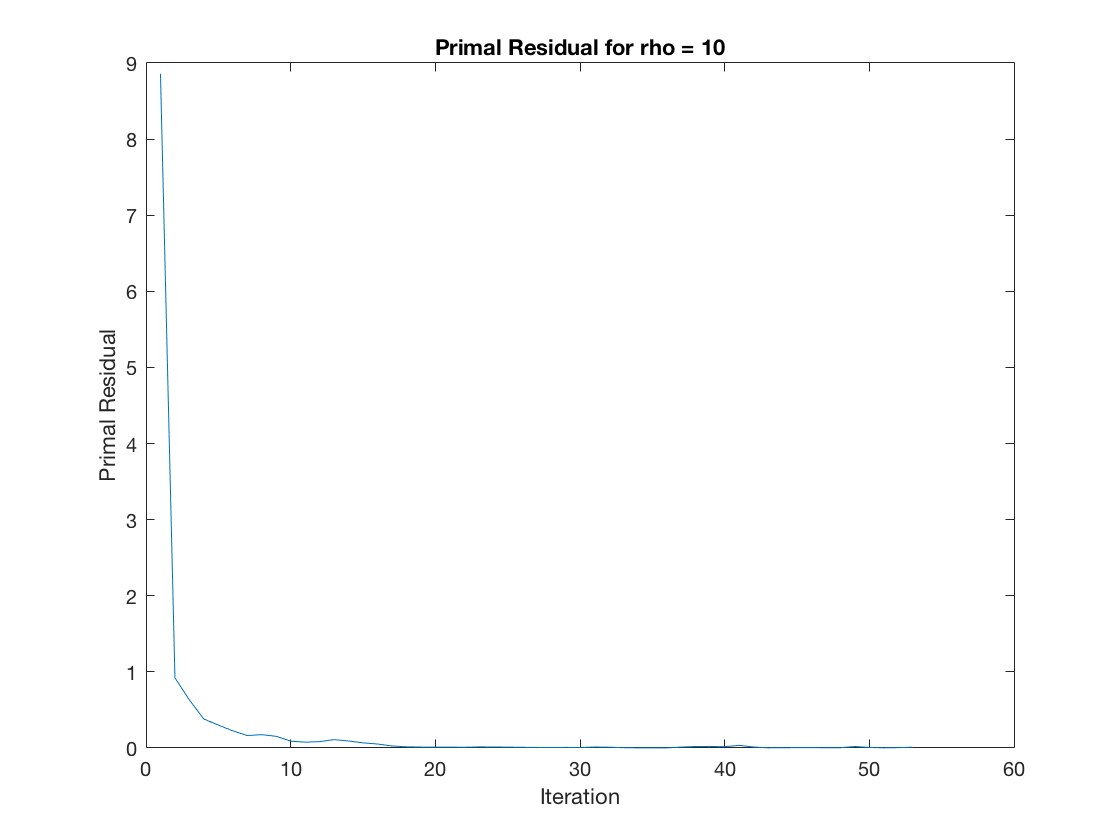

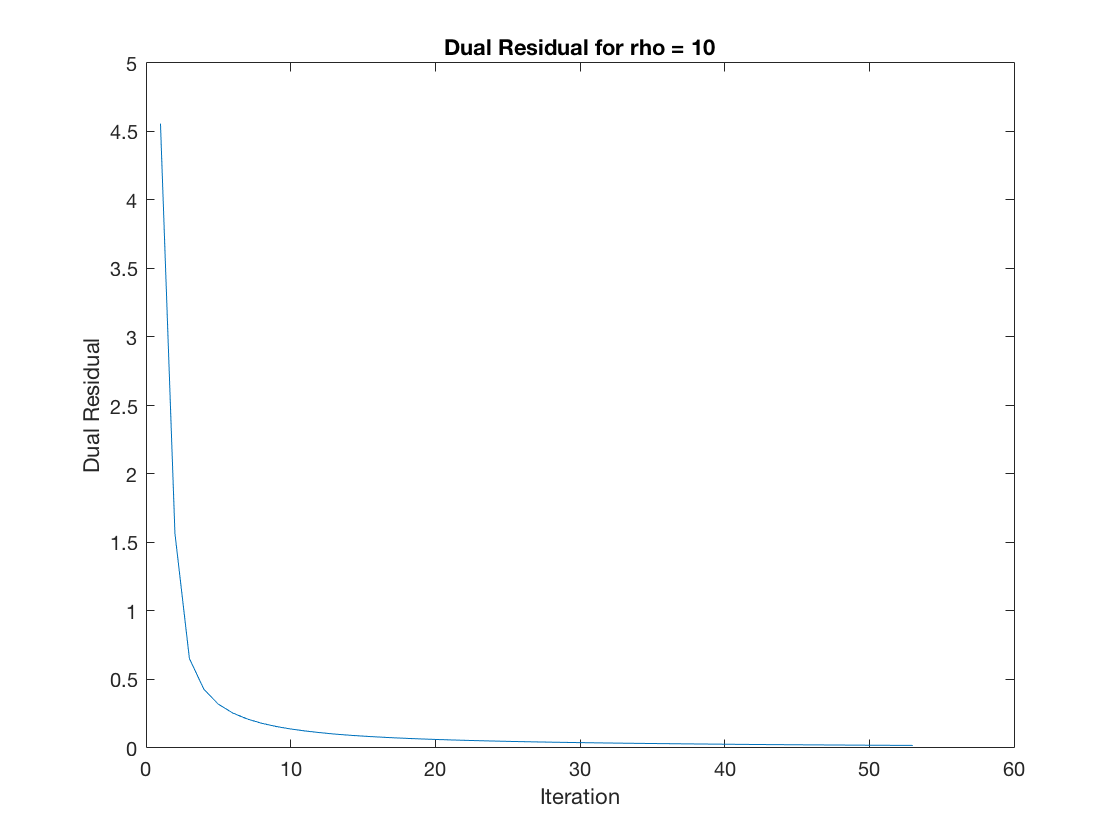

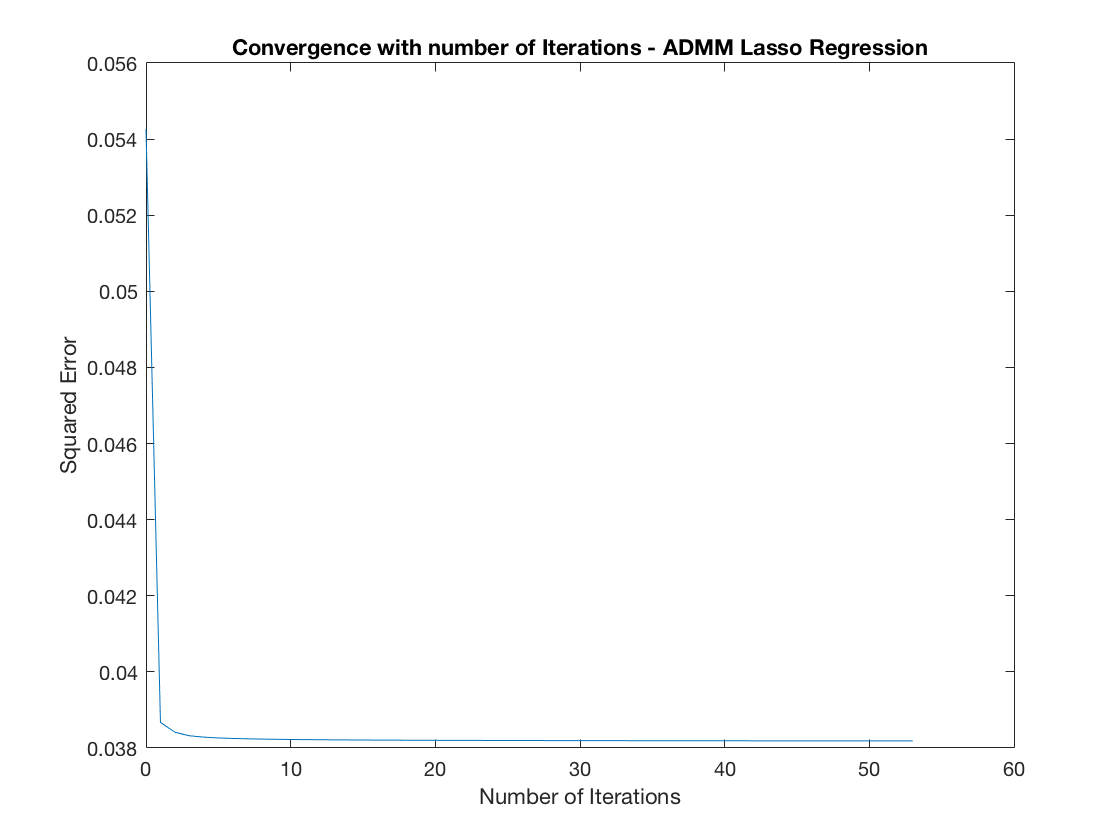



tic
[err_admm, theta_admm] = LassoADMM(x, y, lda, rho, abs_tolerance, rel_tolerance, iters);

t_admm = toc;


tic
theta_activeset = LassoActiveSet(x, y, 1.5);

      iter            n(w)         n(step)            f(w) opt(wi)  free
         1        0.00e+00        0.00e+00        1.09e+04  1387     0
         2        1.16e+00        1.16e+00        1.09e+04  1388     1
         3        1.50e+00        4.24e-01        1.08e+04  4211     2
Not Sign Feasible
It is still Sign Infeasible
Finally, it is sign feasible
         4        1.50e+00        8.41e-01        1.08e+04  9838     2
         5        1.50e+00        9.03e-01        1.08e+04  9973     3
         6        1.50e+00        5.99e-01        1.08e+04  9990     4
         7        1.50e+00        2.61e-01        1.08e+04  9993     5
         8        1.50e+00        2.76e-01        1.08e+04  9998     6
         9        1.50e+00        1.46e-01        1.08e+04  9999     7
        10        1.50e+00        8.14e-02        1.08e+04 10000     8
All Components satisfy condition
Number of iterations: 10


t_activeset = toc;
err_activeset = (1/(2*m))*sum((y - x*theta_activeset).^2)

err_activeset = 0.0542

tic
theta_blockcoordinate = LassoBlockCoordinate(x, y, 1.5);

 iter         n(step)            f(w)
    1     7.91550e-01     1.10693e+04
    2     7.02666e-01     1.10687e+04
    3     8.68824e-01     1.10680e+04
    4     7.78472e-01     1.10677e+04
    5     1.02724e+00     1.10670e+04
    6     5.55290e-01     1.10665e+04
    7     2.96657e-01     1.10661e+04
    8     7.05560e-01     1.10657e+04
    9     4.90972e-01     1.10652e+04
   10     7.55784e-01     1.10646e+04
   11     3.76113e-01     1.10642e+04
   12     5.91647e-01     1.10638e+04
   13     6.10486e-01     1.10633e+04
   14     4.23055e-01     1.10630e+04
   15     6.62459e-01     1.10624e+04
   16     7.12991e-01     1.10620e+04
   17     7.18387e-01     1.10613e+04
   18     4.95822e-01     1.10609e+04
   19     3.67267e-01     1.10607e+04
   20     1.03447e+00     1.10600e+04
   21     6.46118e-01     1.10595e+04
   22     5.79571e-01     1.10594e+04
   23     5.06664e-01     1.10590e+04
   24     8.84035e-01     1.10584e+04
   25     7.44719e-01     1.10579e+04
   26     5.

t_blockcoordinate = toc;
err_blockcoordinate = (1/(2*m))*sum((y - x*theta_blockcoordinate).^2)

err_blockcoordinate = 0.0477

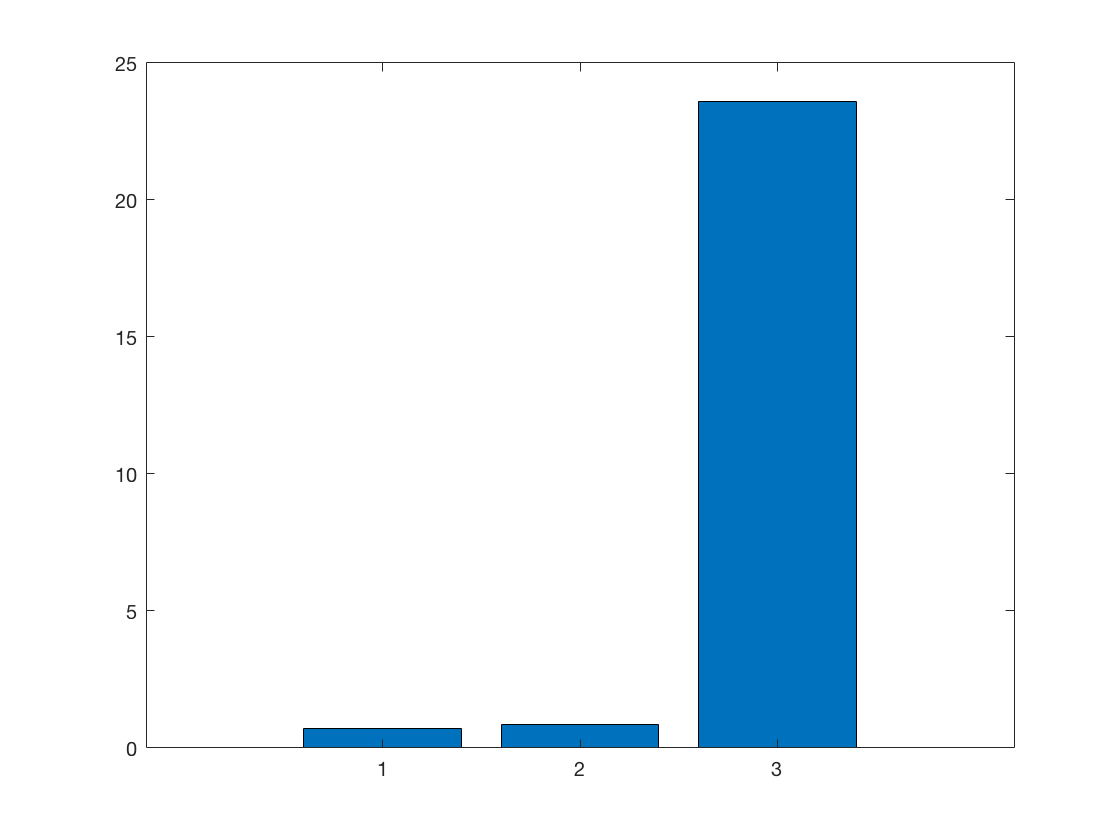

figure;
bar([t_admm, t_activeset, t_blockcoordinate]);

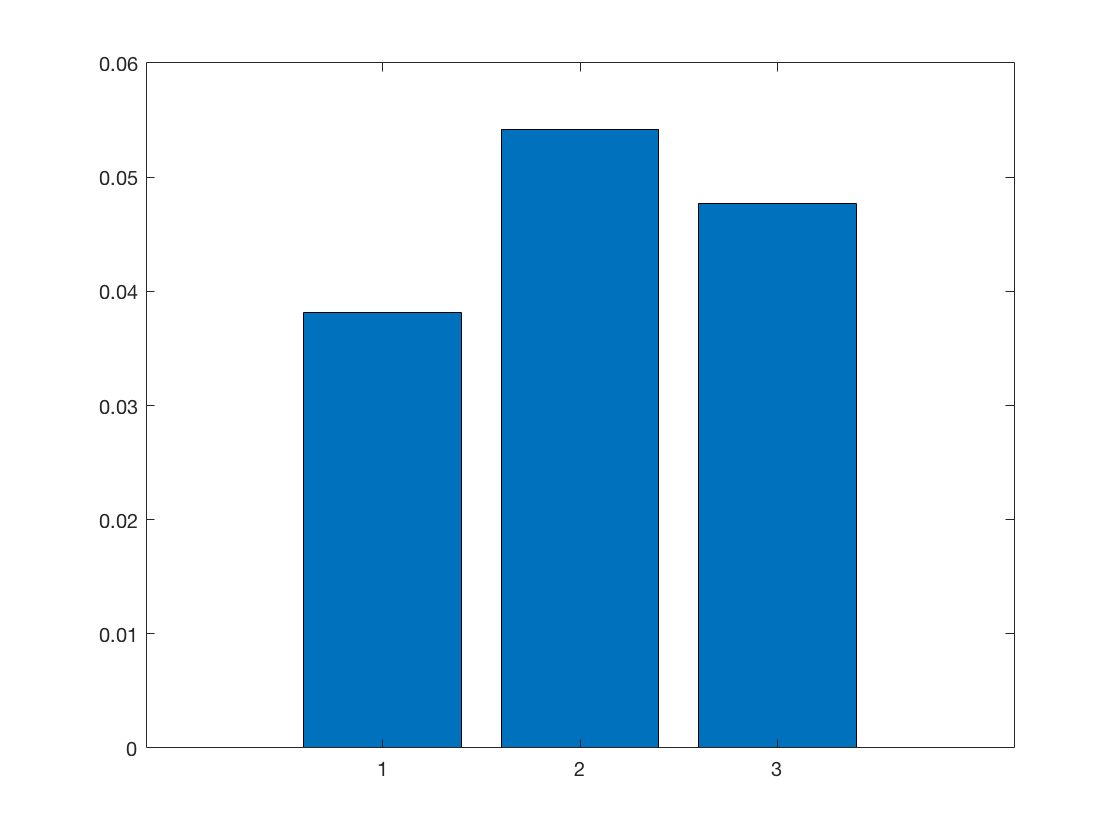

figure;
bar([err_admm err_activeset err_blockcoordinate]);

nnz(theta_admm)

ans = 8415

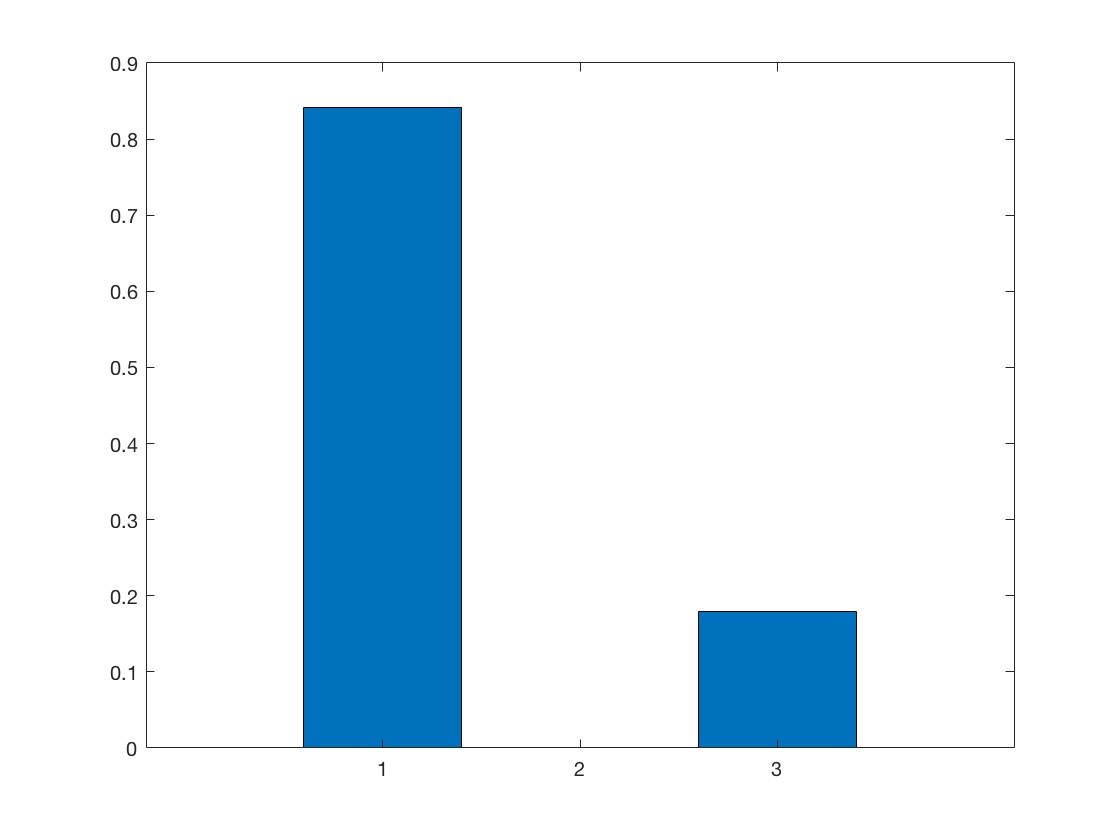

density = [nnz(theta_admm)/n; nnz(theta_activeset)/n; nnz(theta_blockcoordinate)/n];
figure;
bar(density);

clear;
m = 100000;
n = 10000;
density = 2/m;
lda = 0.01;
rho = 0.1;
abs_tolerance = 1e-4;
rel_tolerance = 1e-3;
x = sprandn(m, n, density);
y = randn(m, 1);
iters = 1000;

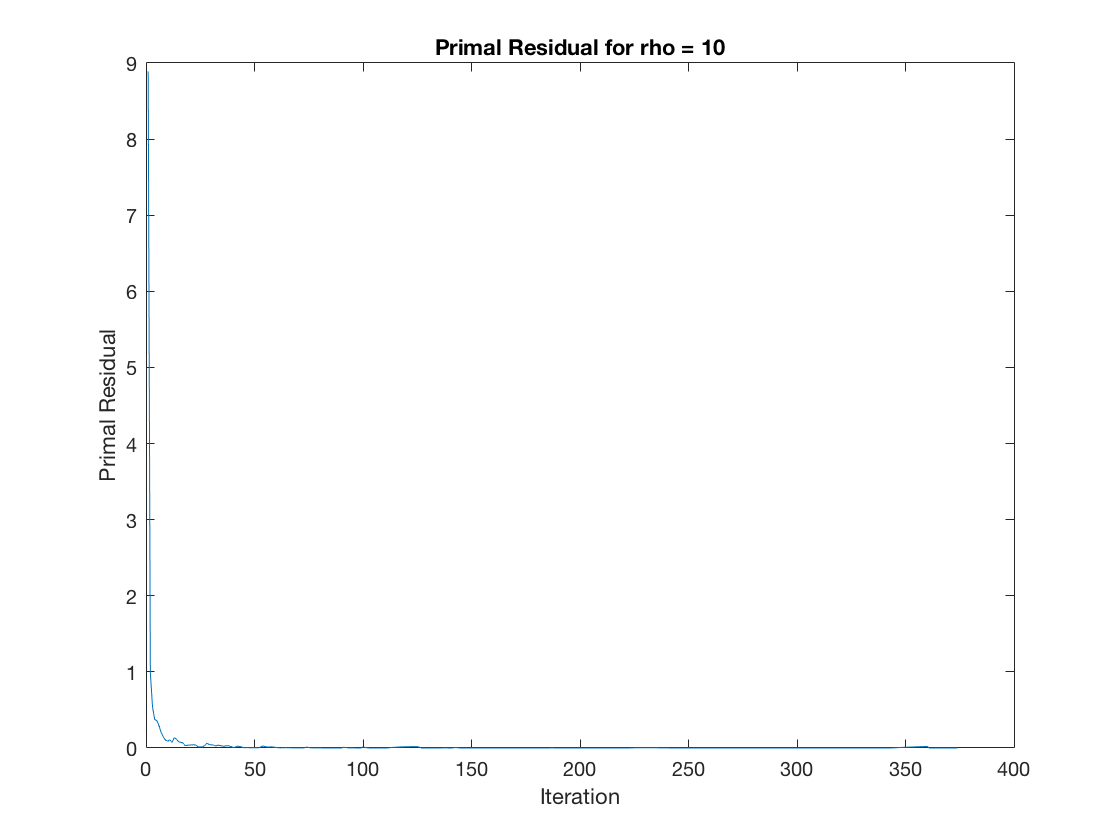

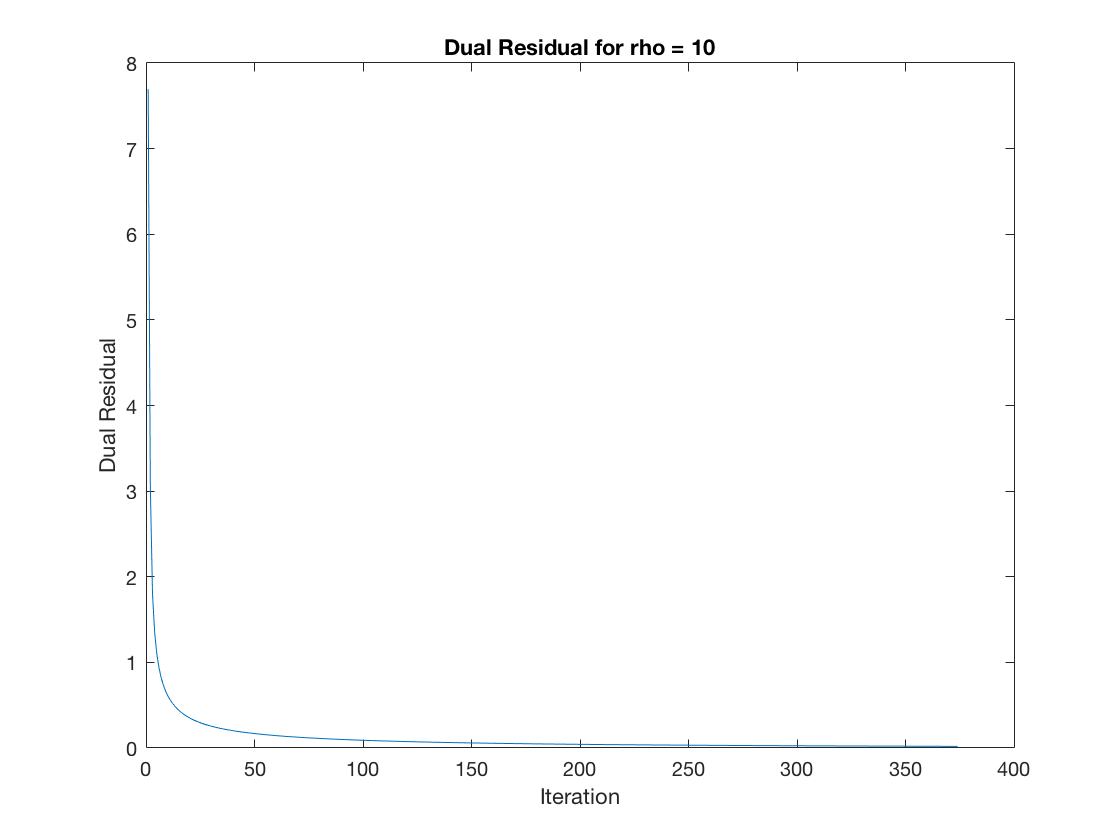

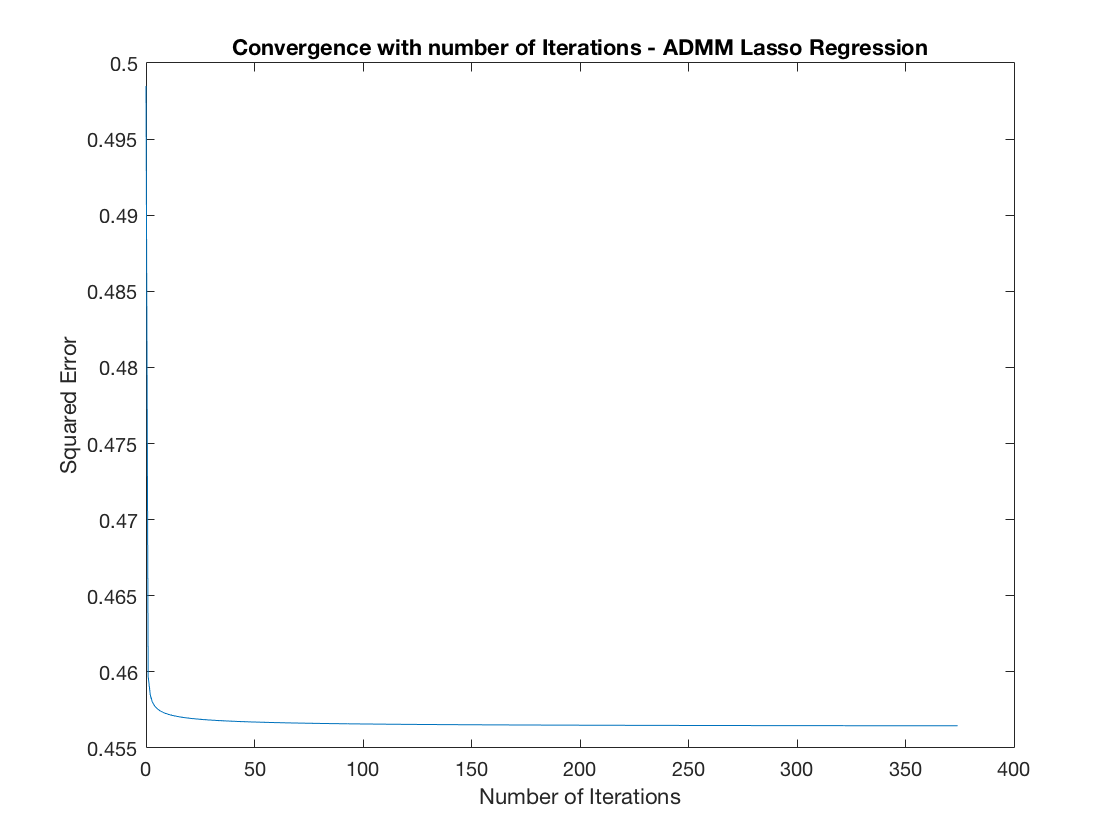

tic
[err_admm, theta_admm] = LassoADMM(x, y, lda, rho, abs_tolerance, rel_tolerance, iters);

t_admm = toc;


tic
theta_activeset = LassoActiveSet(x, y, 1.5);

      iter            n(w)         n(step)            f(w) opt(wi)  free
         1        0.00e+00        0.00e+00        9.97e+04  1365     0
         2        1.50e+00        1.50e+00        9.97e+04  6111     1
         3        1.50e+00        8.37e-01        9.97e+04  9436     2
         4        1.50e+00        5.53e-01        9.97e+04  9774     3
         5        1.50e+00        6.59e-01        9.97e+04  9916     4
         6        1.50e+00        6.30e-01        9.97e+04  9957     5
         7        1.50e+00        4.26e-01        9.97e+04  9976     6
         8        1.50e+00        2.33e-01        9.97e+04  9979     7
         9        1.50e+00        1.82e-01        9.97e+04  9986     8
        10        1.50e+00        1.63e-01        9.97e+04  9987     9
        11        1.50e+00        1.30e-01        9.97e+04  9989    10
        12        1.50e+00        5.15e-02        9.97e+04  9991    11
        13        1.50e+00        9.41e-02        9.97e+04  9994    12
    

t_activeset = toc;
err_activeset = (1/(2*m))*sum((y - x*theta_activeset).^2)

err_activeset = 0.4984

tic
theta_blockcoordinate = LassoBlockCoordinate(x, y, 1.5);

 iter         n(step)            f(w)
    1     6.99593e-01     9.76632e+04
    2     9.74610e-01     9.76630e+04
    3     6.28069e-01     9.76626e+04
    4     5.62853e-01     9.76624e+04
    5     4.53545e-01     9.76622e+04
    6     1.08141e+00     9.76618e+04
    7     5.31985e-01     9.76614e+04
    8     5.98542e-01     9.76611e+04
    9     5.06544e-01     9.76608e+04
   10     4.43700e-01     9.76604e+04
   11     8.58194e-01     9.76600e+04
   12     5.56858e-01     9.76598e+04
   13     7.12563e-01     9.76593e+04
   14     4.37349e-01     9.76589e+04
   15     5.58225e-01     9.76586e+04
   16     7.51520e-01     9.76581e+04
   17     6.05648e-01     9.76576e+04
   18     1.01303e+00     9.76571e+04
   19     6.18879e-01     9.76567e+04
   20     5.72900e-01     9.76564e+04
   21     2.26439e-01     9.76562e+04
   22     3.62012e-01     9.76560e+04
   23     2.44389e-01     9.76559e+04
   24     7.76082e-01     9.76555e+04
   25     5.36715e-01     9.76551e+04
   26     6.

t_blockcoordinate = toc;
err_blockcoordinate = (1/(2*m))*sum((y - x*theta_blockcoordinate).^2)

err_blockcoordinate = 0.4724

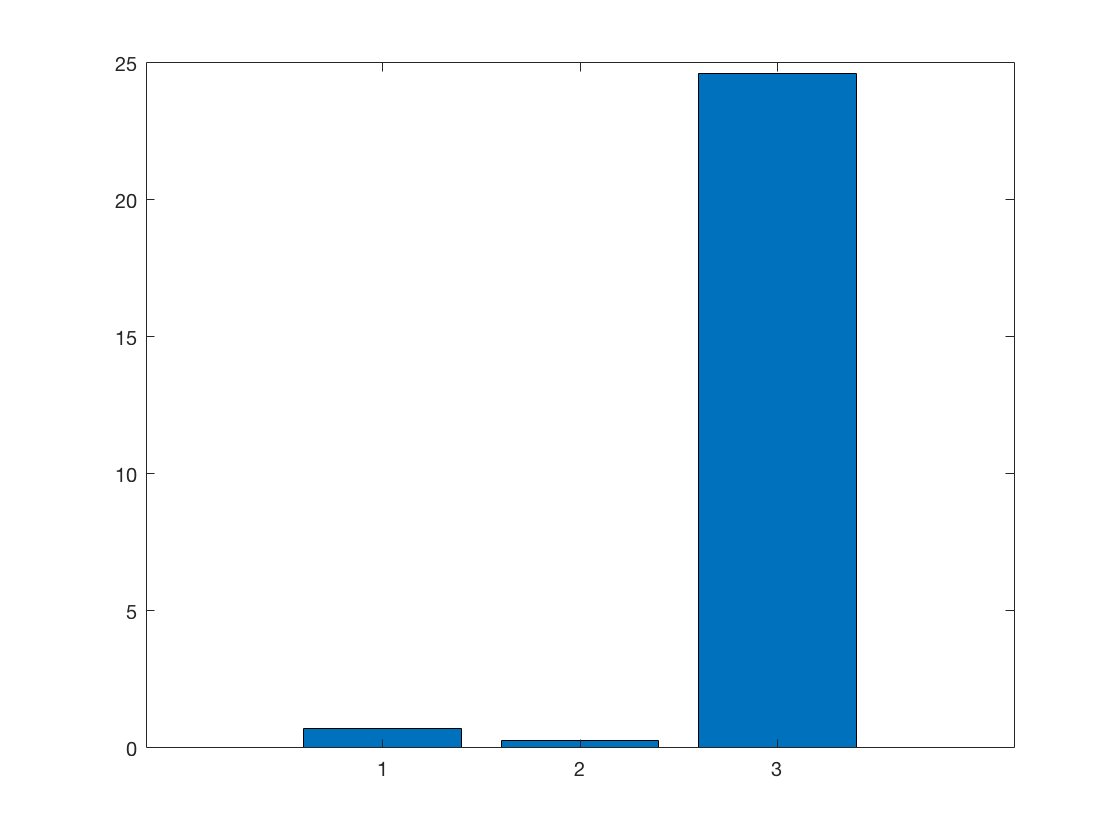

figure;
bar([t_admm, t_activeset, t_blockcoordinate]);

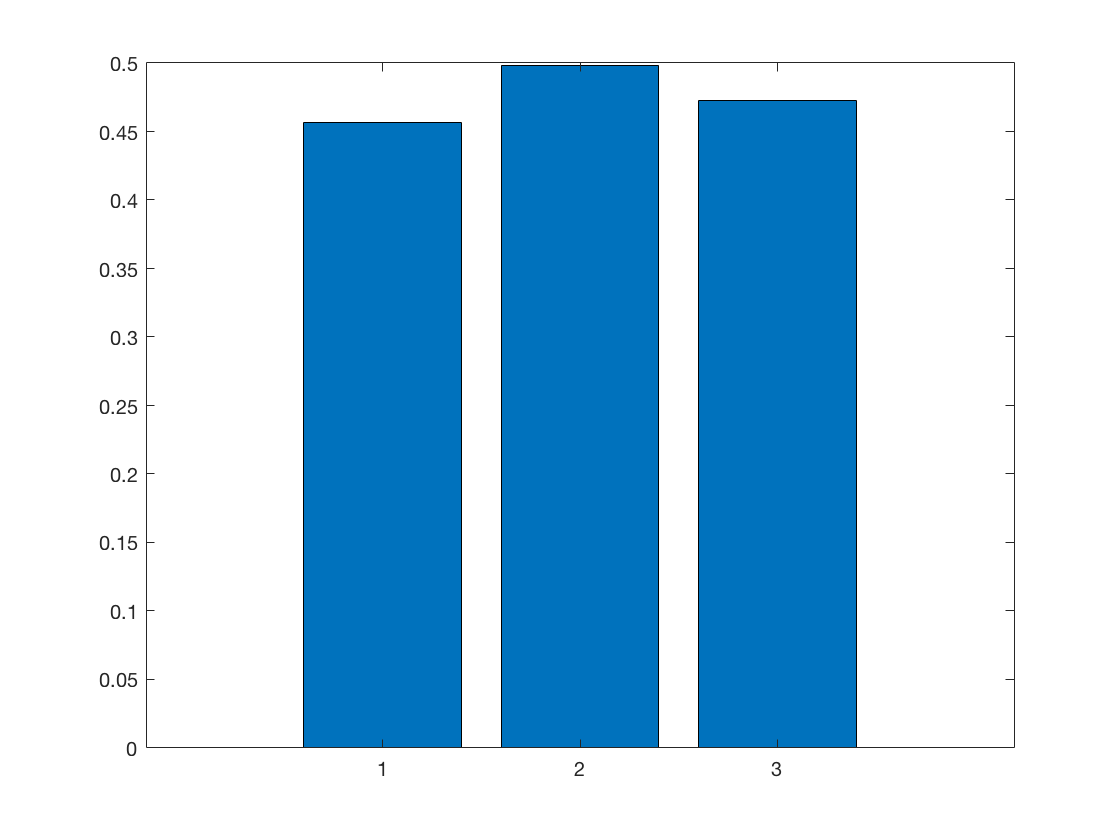

figure;
bar([err_admm err_activeset err_blockcoordinate]);

nnz(theta_admm)

ans = 8534

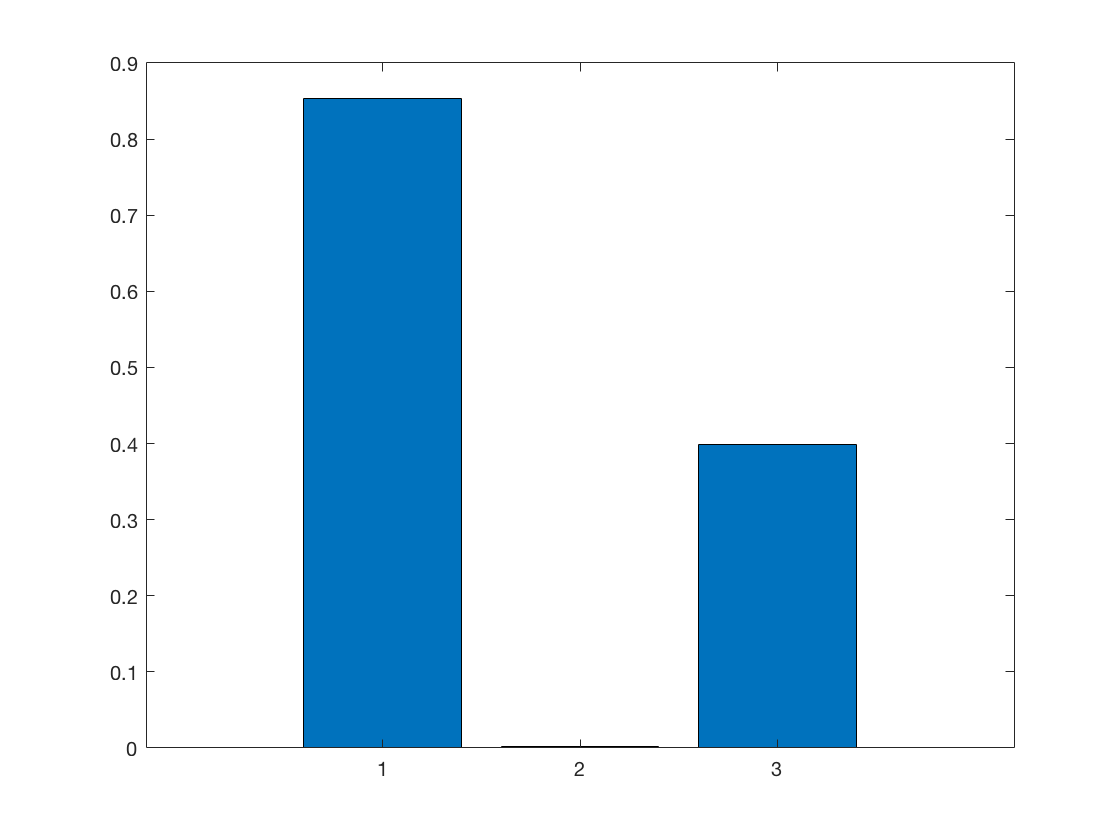

density = [nnz(theta_admm)/n; nnz(theta_activeset)/n; nnz(theta_blockcoordinate)/n];
figure;
bar(density);